# Simulation Of Ground Acceleration Record

Time series of acceleration records are simulated using a stationary process that is "weighted" by an envelope function. The function that fulfils this procedure is 'seismSim'. The parameters of the simulated seismic record are retrieved using the function 'fitKT'

## Ground acceleration record computation

%frequency vector
f = linspace(0,48,4096);
f

f =          0    0.0117    0.0234    0.0352    0.0469    0.0586    0.0703    0.0821    0.0938    0.1055    0.1172    0.1289    0.1407    0.1524    0.1641    0.1758    0.1875    0.1993    0.2110    0.2227    0.2344    0.2462    0.2579    0.2696    0.2813    0.2930    0.3048    0.3165    0.3282    0.3399    0.3516    0.3634    0.3751    0.3868    0.3985    0.4103    0.4220    0.4337    0.4454    0.4571    0.4689    0.4806    0.4923    0.5040    0.5158    0.5275    0.5392    0.5509    0.5626    0.5744


- select `bandwidth of the earthquake excitation`

zeta = 0.3;

- select the standard deviation of `earthquake excitation`

sigma = 0.35;

- select `dominant frequency of the earthquake excitation (Hz).`

fn = 10;

- select `value of the envelop function at 90 percent of the duration.`

T90 = 0.25;

- select `normalized duration time when ground motion achieves peak.`

eps = 0.4;

- **select **duration of ground motion;

tn = 60;

Calling this function

% function call
[y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn); 
% y: acceleration record
% t: time

### Plot Function

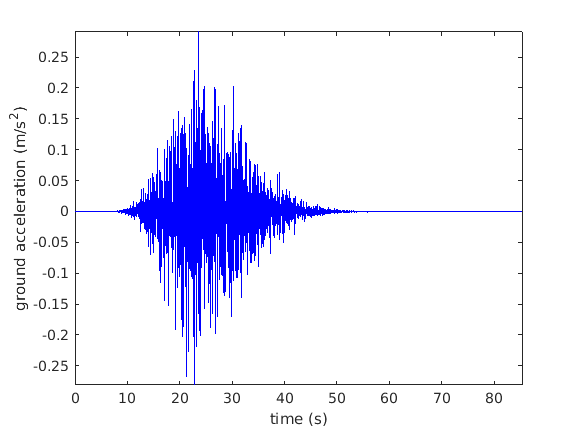

plot(t,y,'b');
xlabel('time (s)')
ylabel('ground acceleration (m/s^2)')
axis tight

Earthquake data has been generated.

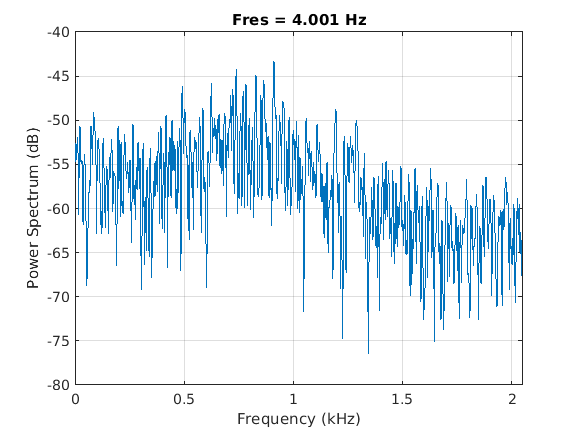

pspectrum(y,4096,"power")

Now let's check any burst of energy correspond to Earthquake record and measure the length of any such burst

env = envelope(y,40,"rms");
pulsewidth(env,4096)

ans = 0.2235

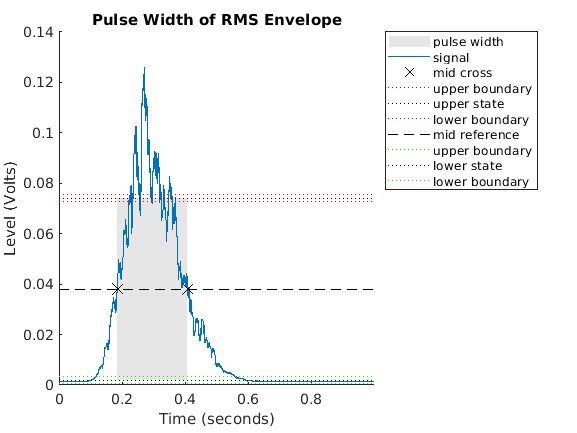

title("Pulse Width of RMS Envelope")

We can clearly see the pulse width of 200 millisecond for some frequency which exists the earthquake means our domain value but we cannot say what is the frequency level from this.

let's go to our frequency plot and tries to figure it out the ranges over which our earthquake get power(strong motion acceleration).

meanf = [meanfreq(y,4096,[500,700]),...
        meanfreq(y,4096,[700,1000]),...
        meanfreq(y,4096,[1000,1500]),...
        meanfreq(y,4096,[1500,2000])
    ];

    round(meanf)

ans =          602         839        1198        1737


Now let's compute the spectrogram to visualize the actual time frequency representation of the signal

    pspectrum(y,4096,"spectrogram","Leakage",1,"FrequencyLimits",[500,1500 ...

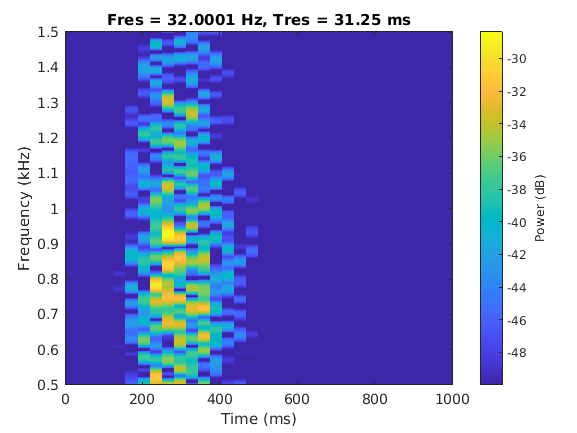

        ],"OverlapPercent",0,"MinThreshold",-50)

# Getting best representation of the signal considering the trade-off of time and frequency

**Note: **our signal is sampled @4kHz rate. 

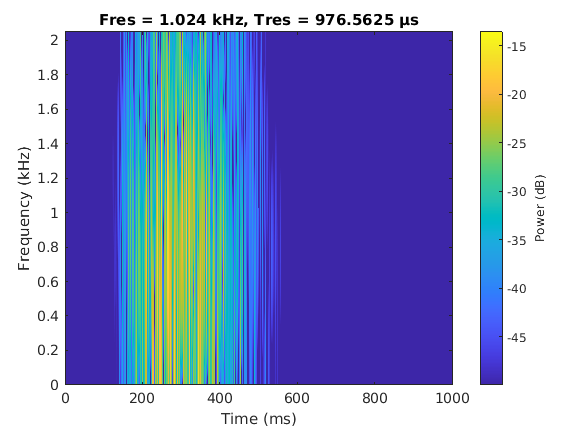

pspectrum(y,4096,"spectrogram","OverlapPercent",0,...
    "Leakage",1,"MinThreshold",-50,"TimeResolution",1e-3)

Compute the Fourier transform of the signal, and create the vector `f` that corresponds to the signal's sampling in frequency space.

x = fft(y);     
f = (0:length(x)-1)*50/length(x);

Plotting of signal in frequency domain

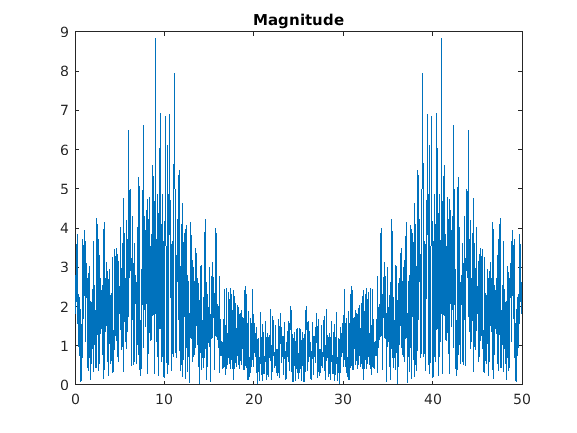

plot(f,abs(x))
title('Magnitude')

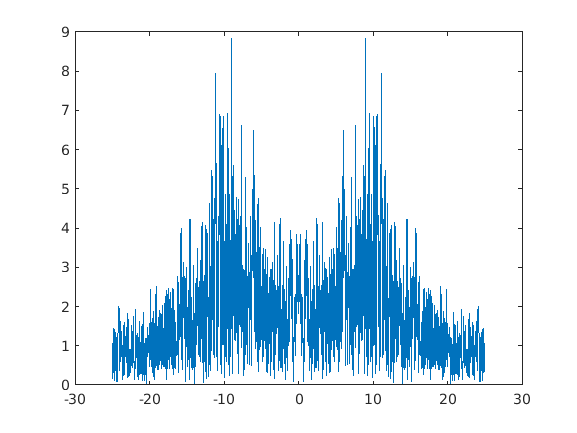

n = length(y);                         
fshift = (-n/2:n/2-1)*(50/n);
yshift = fftshift(x);
plot(fshift,abs(yshift))

### The time-domain plot of the signal confirms the presence of  bursts of energy, corresponding to earthquake strong motion. To measure the length of the burst, we will take the pulse width of the RMS envelope.

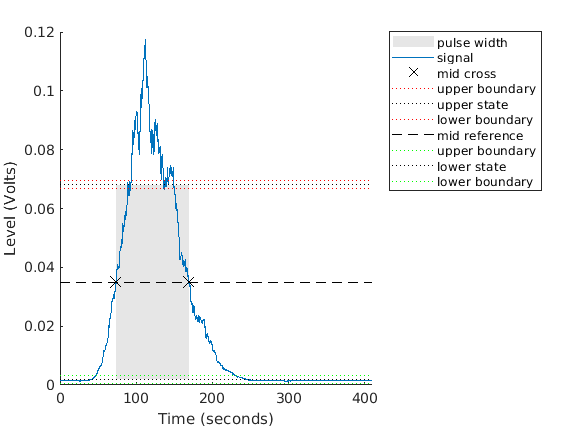

ans = 95.5404


env = envelope(y,80,'rms');
pulsewidth(env,fn)

pspectrum(y,fn,'spectrogram','Leakage',1,'OverlapPercent',0, ...
    'MinThreshold',-10);

### Writting Our Own STFT function:

In this module we are going to write our very own module of STFT code based on theory described in 

[1] H. Zhivomirov. On the Development of STFT-analysis and ISTFT-synthesis Routines and their Practical Implementation. TEM Journal, ISSN: 2217-8309, DOI: 10.18421/TEM81-07, Vol. 8, No. 1, pp. 56-64, Feb. 2019. ([http://www.temjournal.com/content/81/TEMJournalFebruary2019_56_64.pdf](http://www.temjournal.com/content/81/TEMJournalFebruary2019_56_64.pdf))




%acceleration record
y;
%dominant frequency
fn

fn = 10

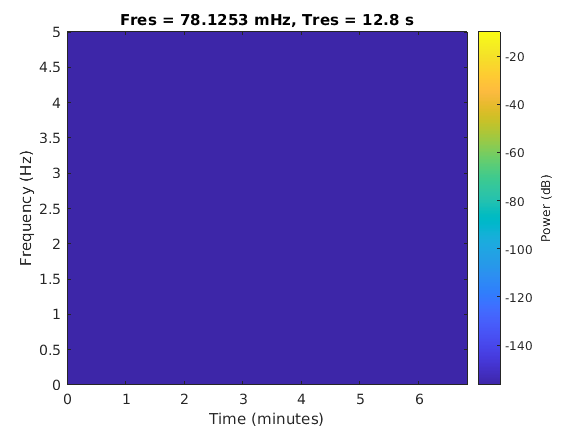

% define analysis parameters
wlen = 1024;                        % window length (recomended to be power of 2)
hop = wlen/4;                       % hop size (recomended to be power of 2)
nfft = 4096;                        % number of fft points (recomended to be power of 2)
% perform STFT
win = blackman(wlen, 'periodic');
[S, f, t] = cstft(y, win, hop, nfft, fn);
% calculate the coherent amplification of the window
C = sum(win)/wlen;
% take the amplitude of fft(x) and scale it, so not to be a
% function of the length of the window and its coherent amplification
S = abs(S)/wlen/C;
% correction of the DC & Nyquist component
if rem(nfft, 2)                     % odd nfft excludes Nyquist point
    S(2:end, :) = S(2:end, :).*2;
else                                % even nfft includes Nyquist point
    S(2:end-1, :) = S(2:end-1, :).*2;
end
% convert amplitude spectrum to dB (min = -120 dB)
S = 20*log10(S + 1e-6);
% plot the spectrogram
figure(1)

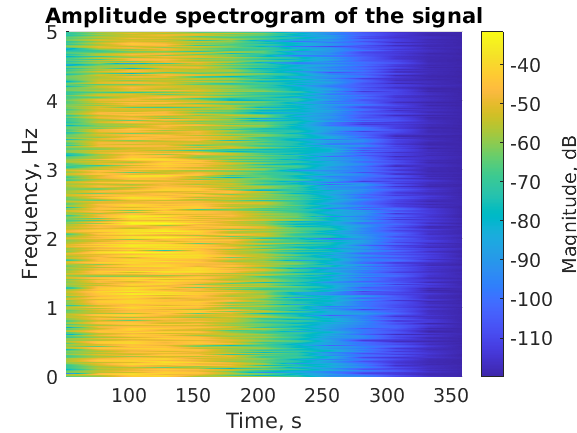

surf(t, f, S)
shading interp
axis tight
view(0, 90)
set(gca, 'FontName', 'Times New Roman', 'FontSize', 14)
xlabel('Time, s')
ylabel('Frequency, Hz')
title('Amplitude spectrogram of the signal')
hcol = colorbar;
set(hcol, 'FontName', 'Times New Roman', 'FontSize', 14)
ylabel(hcol, 'Magnitude, dB')

### 3D STFT VISUALIZATION;

Compute and plot the STFT of the signal. Use a Kaiser window of length 256 and shape parameter *β*=5. Specify the length of overlap as 220 samples and DFT length as 512 points. Plot the STFT with default colormap and view.

stft(y,4096,'Window',kaiser(256,5),'OverlapLength',220,'FFTLength',512);

Change the view to display the STFT as a waterfall plot. Set the colormap to `jet`.

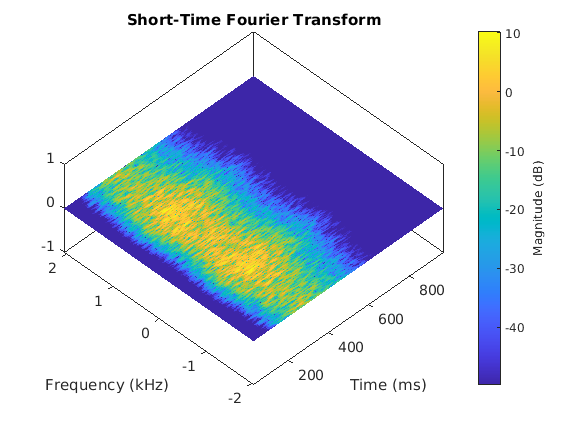

view(-45,65)

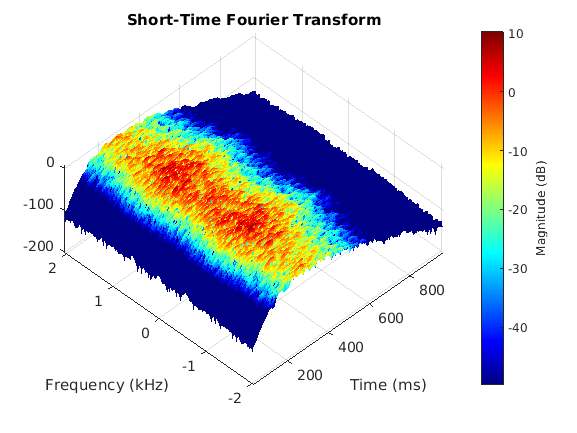

colormap jet

#### Simulation Function:

function [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn)
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn) generate one time series
% corresponding to acceleration record from a seismometer. The function
% requires 7 inputs, and gives 2 outputs. The time series is generated in
% two steps: First a stationnary process is created based on the Kanai-
% Tajimi spectrum, then an envelope function is used to transform this 
% stationnary time series into a non-stationary record. For more
% information, see [1-3].
% [1] Lin, Y. K., & Yong, Y. (1987). Evolutionary Kanai-Tajimi earthquake
% models. Journal of engineering mechanics, 113(8), 1119-1137.
% [2] Rofooei, F. R., Mobarake, A., & Ahmadi, G. (2001). 
% Generation of artificial earthquake records with a nonstationary 
% KanaiTajimi model. Engineering Structures, 23(7), 827-837.
% [3] Guo, Y., & Kareem, A. (2016). 
% System identification through nonstationary data using TimeFrequency Blind
% Source Separation. Journal of Sound and Vibration, 371, 110-131.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% INPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% sigma: [1 x 1 ]: standard deviation of the excitation.
% fn: [1 x 1 ]: dominant frequency of the earthquake excitation (Hz).
% zeta: [1 x 1 ]:  bandwidth of the earthquake excitation.
% f: [ 1 x M ]: frequency vector for the Kanai-tajimi spectrum.
% T90: [1 x 1 ]: value at 90 percent of the duration.
% eps: [1 x 1 ]: normalized duration time when ground motion achieves peak.
% tn: [1 x 1 ]: duration of ground motion.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% OUTPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% y: size: [ 1 x N ] : Simulated aceleration record
% t: size: [ 1 x N ] : time
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% EXAMPLE:
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% f = linspace(0,40,2048);
% zeta = 0.3;
% sigma = 0.9;
% fn =5;
% T90 = 0.3;
% eps = 0.4;
% tn = 30;
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn);
% figure
% plot(t,y);axis tight
% xlabel('time(s)');
% ylabel('ground acceleration (m/s^2)')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% see also fitKT.m
% Author: Etienne Cheynet - modified: 23/04/2016

%% Initialisation
w = 2*pi.*f;
fs = f(end); dt = 1/fs;
f0= median(diff(f));
Nfreq = numel(f);
t = 0:dt:dt*(Nfreq-1);

%% Generation of the spectrum S
fn = fn *2*pi; % transformation in rad;
s0 = 2*zeta*sigma.^2./(pi.*fn.*(4*zeta.^2+1));
A = fn.^4+(2*zeta*fn*w).^2;
B = (fn.^2-w.^2).^2+(2*zeta*fn.*w).^2;
S = s0.*A./B; % single sided PSD


%% Time series generation - Monte Carlo simulation
A = sqrt(2.*S.*f0);
B =cos(w'*t + 2*pi.*repmat(rand(Nfreq,1),[1,Nfreq]));
x = A*B; % stationary process

%% Envelop function E
b = -eps.*log(T90)./(1+eps.*(log(T90)-1));
c = b./eps;
a = (exp(1)./eps).^b;
E = a.*(t./tn).^b.*exp(-c.*t./tn);

%% Envelop multiplied with stationary process to get y
y = x.*E;

end

### CUSTOM STFT FUNCTION

function [STFT, f, t] = cstft(x, win, hop, nfft, fs)
% function: [STFT, f, t] = stft(x, win, hop, nfft, fs)
%
% Input:
% x - signal in the time domain
% win - analysis window function
% hop - hop size
% nfft - number of FFT points
% fs - sampling frequency, Hz
%
% Output:
% STFT - STFT-matrix (only unique points, time 
%        across columns, frequency across rows)
% f - frequency vector, Hz
% t - time vector, s
% representation of the signal as column-vector
x = x(:);
% determination of the signal length 
xlen = length(x);
% determination of the window length
wlen = length(win);
% stft matrix size estimation and preallocation
NUP = ceil((1+nfft)/2);     % calculate the number of unique fft points
L = 1+fix((xlen-wlen)/hop); % calculate the number of signal frames
STFT = zeros(NUP, L);       % preallocate the stft matrix
% STFT (via time-localized FFT)
for l = 0:L-1
    % windowing
    xw = x(1+l*hop : wlen+l*hop).*win;
    
    % FFT
    X = fft(xw, nfft);
    
    % update of the stft matrix
    STFT(:, 1+l) = X(1:NUP);
end
% calculation of the time and frequency vectors
t = (wlen/2:hop:wlen/2+(L-1)*hop)/fs;
f = (0:NUP-1)*fs/nfft;
end